## Definitions of constants/variables

%More Background Research (transceiver design and general trends in industry)

%Resetting the rng seed
rng("default");
rng(1960);

symbol_num = 32*1024; 

%%Sets of signals to be manipulated in different ways
%These sets are also the SNR Values
sets = linspace(1,50,30);
sets_num = length(sets);

symbol_rate = 100e9; %Hz
time_step = 1/symbol_rate; %seconds
linewidth = 100e3; %Hz
variance=2*pi*linewidth*time_step;


symbols = randi([0 3],1,symbol_num);



## QPSK and Phase Noise

modulated_symbols = pskmod(symbols,4,0,'gray');
%demod_symbols = pskdemod(modulated_symbols,4,0,'gray');

%%%Phase noise modeled as random walk%%%
% The cummulative sum of the standard deviations of each symbol's 
% phase as they are passed through the channel

phase_noise = randn(1,symbol_num);

variances = (variance .* sets)';

phase_noise_sets = exp(1j*cumsum(sqrt(variances).* phase_noise));

%%% Both phase and amplitude modified:
%phase_noise_sets = cumsum(sqrt(variances).*exp(1j*phase_noise));

%noisy_modulated_symbols = modulated_symbols .* phase_noise_sets;
%noisy_demod_symbols = pskdemod(noisy_modulated_symbols,4,0,"gray");


## SNR and BER for AWGN and Phase Noise

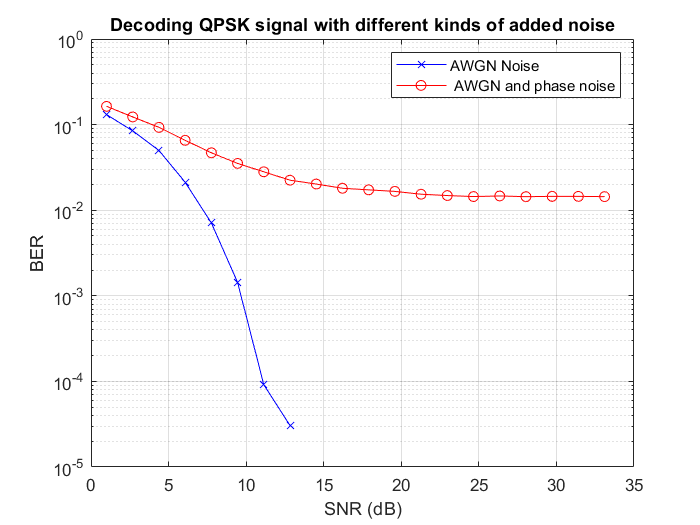

snr_values = sets;

awgn_symbol_sets = zeros(1,symbol_num);

for i=1:sets_num
    awgn_symbol_sets(i,:) = awgn(modulated_symbols,snr_values(i));
end

awgn_demod_symbol_sets = pskdemod(awgn_symbol_sets,4,0,"gray");


[~,AWGN_BER] = biterr(symbols,awgn_demod_symbol_sets,2);

figure
semilogy(snr_values,AWGN_BER,"-bx");
title("Decoding QPSK signal with different kinds of added noise");
grid on ;
xlabel("SNR (dB)");
ylabel("BER");
hold on ;

%%Add the largest phase noise and plot on the same graph for comparison
phase_awgn_symbol_sets = awgn_symbol_sets .* phase_noise_sets(sets_num,:);

phase_awgn_demod_symbol_sets = pskdemod(phase_awgn_symbol_sets,4,0,"gray");

[~,PHASE_AWGN_BER] = biterr(symbols,phase_awgn_demod_symbol_sets);

semilogy(snr_values(1,1:20),PHASE_AWGN_BER(1:20,1),"ro-");
legend("AWGN Noise"," AWGN and phase noise");
hold off;

## Digital to Analog Conversion

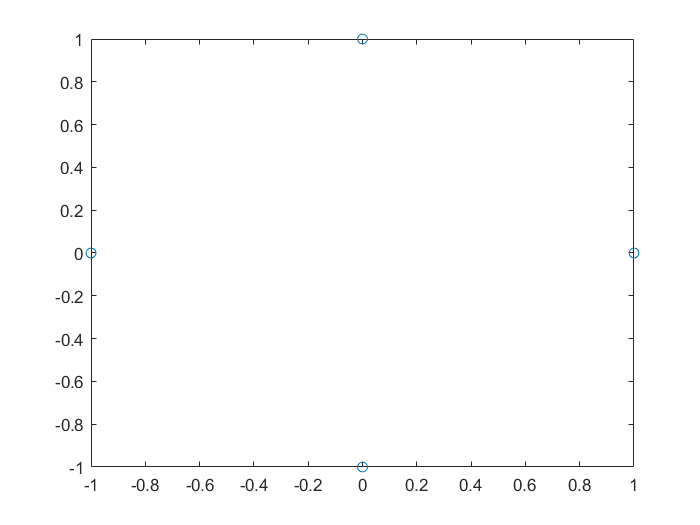

%{
symbol_rate = 100e9; 
time_step = 1/symbol_rate; 
linewidth = 100e3;
variance=2*pi*linewidth*time_step;}
%}

%TODO create symbols of a known sequence for easier debugging
%Look into these (for analog conversion):
%need to downsample
%with integrate and dump 

upscaling = 8;
kron_symbols = kron(symbols,ones(1,upscaling));

mod_kron_symbols = pskmod(kron_symbols,4,0,'gray'); %QPSK gray modulation
plot(mod_kron_symbols,'o');
hold on;


downscaled__mod_symbols = intdump(mod_kron_symbols,upscaling);

demoded_symbols = pskdemod(downscaled__mod_symbols,4,0,'gray');  

## Spectral Analysis

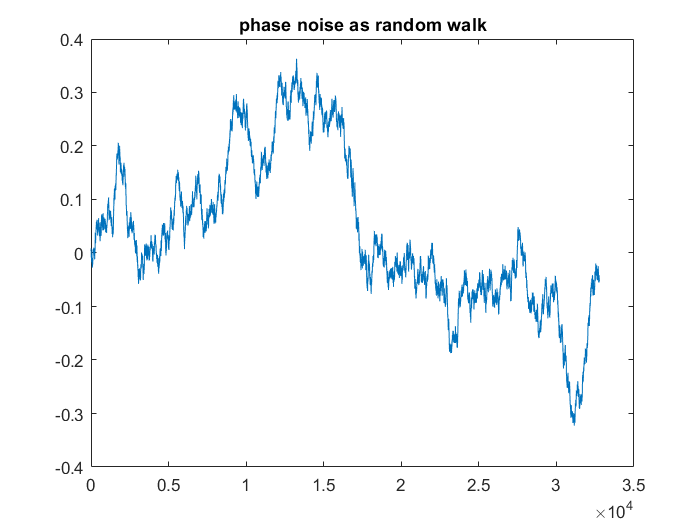

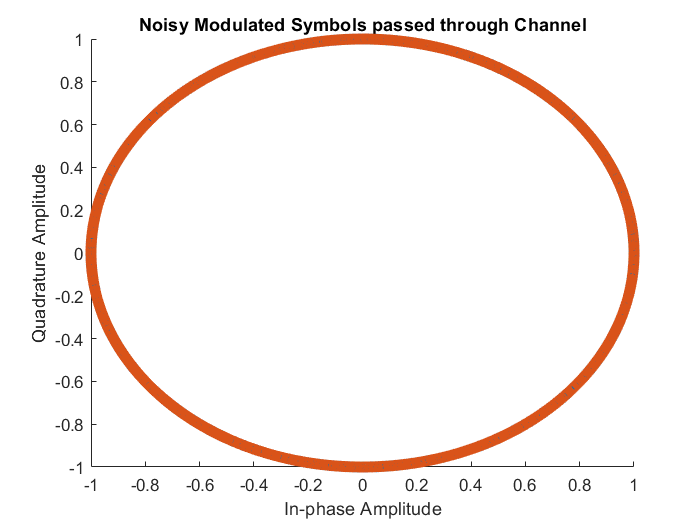

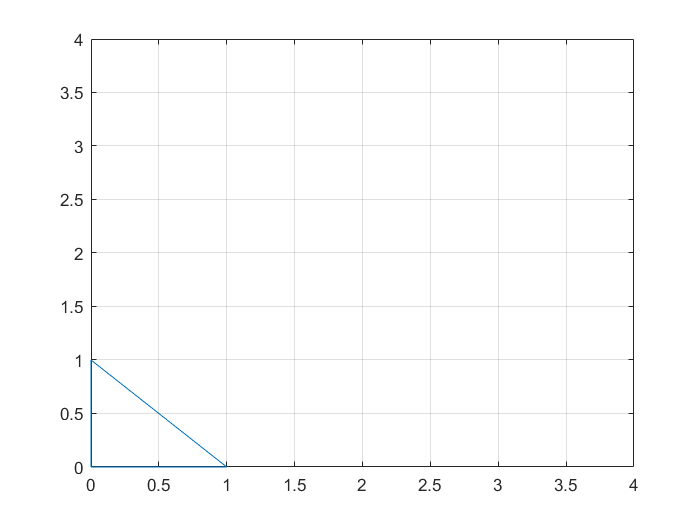

%noisy_modulated_symbols
%symbol_num
%symbol_rate
%time_step

%%Change the symbols to be a known frequency
t = (0:symbol_num-1)/symbol_rate;
freq_inc = symbol_rate/symbol_num;
nyq_freq = symbol_rate/2;
y = zeros(sets_num,symbol_num);
amplitude = zeros(sets_num,symbol_num);
power = zeros(sets_num,symbol_num);
% 
% for i=1:size(phase_noise_only_modsym)
%     y(i,:) = fft(phase_noise_only_modsym(i,:));
%     amplitude(i,:) = abs(awgn_symbol_sets(i,:));
%     power(i,:) = (abs(y(i,:)).^2)/symbol_num;
% end

% for i=1:10
% figure
% plot(power(i,:));
% xlabel("Frequency");
% ylabel("Power");
% 
% figure
% plot(amplitude(i,:));
% xlabel("Frequency");
% ylabel("Amplitude");
% end
no_out=plotting(variance,phase_noise,sets,modulated_symbols,symbols);

%Friday 13th presentation

## **Plotting function**

function no_out = plotting(variance, phase_noise, sets, modulated_symbols, symbols)

sets_num = length(sets);

figure
plot(cumsum(sqrt(variance).*phase_noise))
title('phase noise as random walk')

variances = (variance .* sets)';
phase_noise_sets = exp(1j*cumsum(sqrt(variances).*phase_noise));

phase_noise_only_modsym = modulated_symbols .* phase_noise_sets;
phase_noise_only_demodsym = pskdemod(phase_noise_only_modsym,4,0,"gray");

figure
for i=1:sets_num
    hold on
    scatter(real(phase_noise_only_modsym(i,:)),imag(phase_noise_only_modsym(i,:)));
end
title("Noisy Modulated Symbols passed through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")
hold off

%{
figure
scatter(real(noisy_demod_symbols),imag(noisy_demod_symbols),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")
%}

figure
plot(phase_noise_only_demodsym,symbols,"rs")
title("Transmitted Symbols against Received Symbols")
xlabel("For perfect demodulation there should only be squares on (0,0),(1,1),(2,2),(3,3)")
plot(modulated_symbols)
axis([0,4,0,4])
grid on
no_out=phase_noise_only_demodsym(1,1);
end